# Task 2

#### Task 2.1

Load the lake and show it

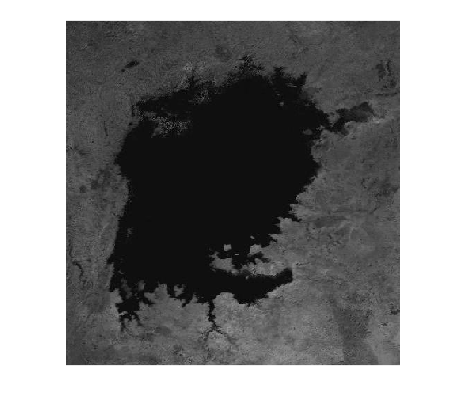

lake = imread("../lake_gray.png");
figure;imshow(lake);

Use k = 2 since we want to classify the lake and a threshold for exiting equal to 0.004

k = 2;
th = 0.005;

Call my implementation

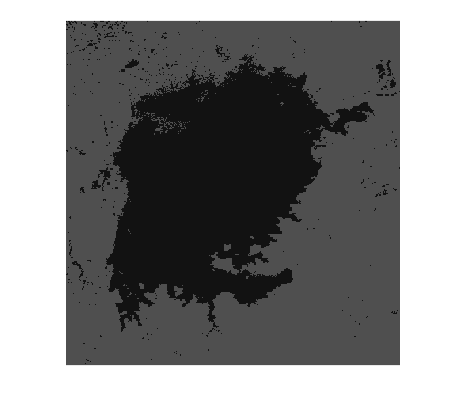

[result,clutered_avg] = (k_means_clustering(lake,k,th));
figure;imshow(remap(result,clutered_avg));

Call the matlab implementation for comparison.

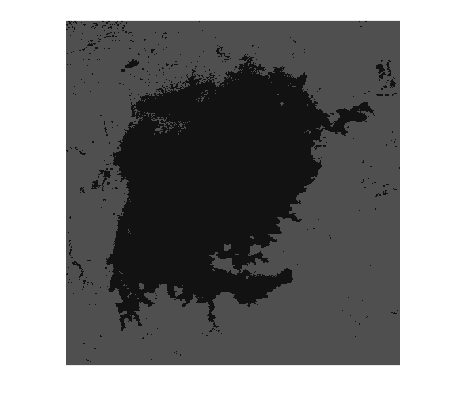

[l,desc]= imsegkmeans(lake,k);
figure;imshow(remap(l,desc));

It is quite apparant that the matlab implementation is faster, but the result achived is verry similar.

Here is the code I used for k_means_clustering

#### Task 2.2

First run SLIC super pixel algorithm from matlab, going to use matlabs k-means here too since it's faster

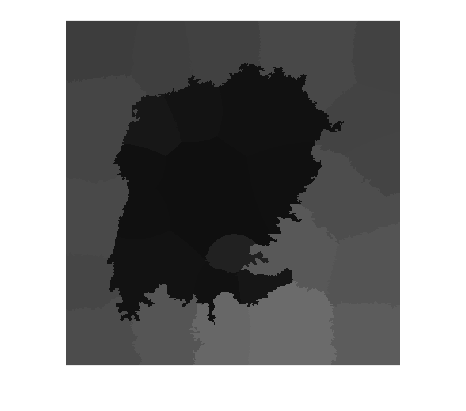

[l,n] = superpixels(lake,30);
img = zeros(size(lake),'like',lake);
super_pixels = label2idx(l);
for i = 1:n
    region = super_pixels{i};
    img(region) = mean(lake(region));
end
figure;
imshow(img);

Now run k means clustering

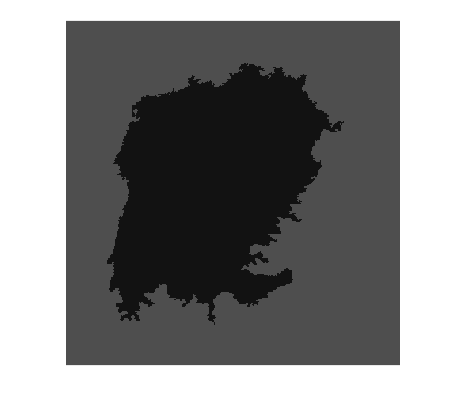

[result,clutered_avg] = (imsegkmeans(img,k));
figure;imshow(remap(result,clutered_avg));

After running the super pixel algorithm first, it seems to have removed a lot of noise.

Trying with a smaller amount of super pixels

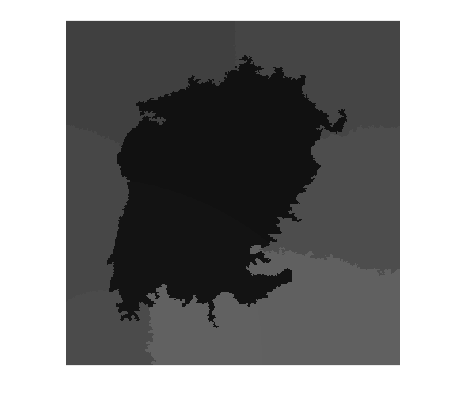

[l,n] = superpixels(lake,10);
img = zeros(size(lake),'like',lake);
super_pixels = label2idx(l);
for i = 1:n
    region = super_pixels{i};
    img(region) = mean(lake(region));
end
figure;
imshow(img);

Now run k means clustering

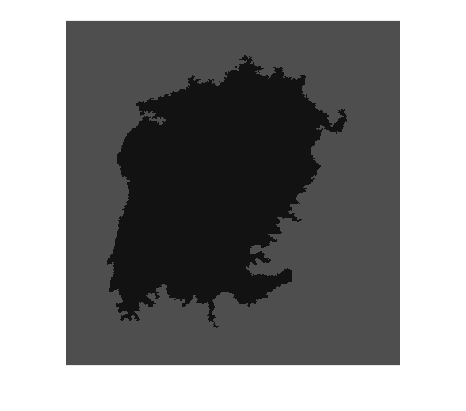

[result,clutered_avg] = (imsegkmeans(img,k));
figure;imshow(remap(result,clutered_avg));

Trying with a larger amount of super pixels

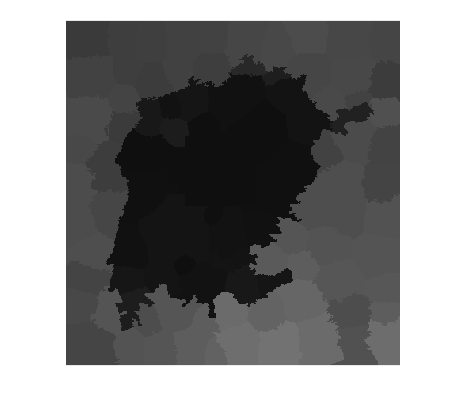

[l,n] = superpixels(lake,100);
img = zeros(size(lake),'like',lake);
super_pixels = label2idx(l);
for i = 1:n
    region = super_pixels{i};
    img(region) = mean(lake(region));
end
figure;
imshow(img);

Now run k means clustering

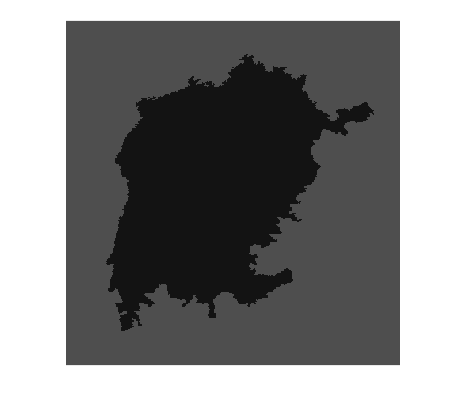

[result,clutered_avg] = (imsegkmeans(img,k));
figure;imshow(remap(result,clutered_avg));

Using super pixels first seems to improve the performance substantially, removing all noise. This is great since the lake is much better segmented after this. Using less super pixels makes us lose some detail in the edges, using more super pixels is better for this task since it allows us to find the outline more precisely

function o = remap(inp,map)
    o = inp;
    for i = 1:size(inp,1)
        for j = 1:size(inp,2)
            o(i,j) = map(inp(i,j));
        end
    end
end